# Decision Tree Classification

In the last lab sheet, we looked at how we could use Decision Tree classification in Matlab. In this lab sheet we're going to go deeper and check that we really understand each of the steps involved in Decision Tree classification. Prerequisites:

- **You need to: (i) download a copy of the ****mytree.m**** class and ****iris.csv**** dataset from Moodle; (ii) store them in the same directory as this live script; and (iii) set Matlab's Current Folder to point at that directory**;

- This script assumes you have completed the Matlab Fundamentals materials.

## Recreating our Matlab results

First let's recreate the results we got in the last lab sheet. If you're not sure about any of the following steps then you need to revisit the previous lab.

Read the dataset:

% read the iris dataset:
data = readtable('iris.csv');

Use it to create a testing dataset (25% of the data) and a training dataset (75% of the data):

% how many examples for 25%:
nTest = round(0.25 * size(data,1))

nTest = 38

% re-seed Matlab's random number generator:
rng(1)
% shuffle the data and create a testing dataset and a training dataset:
data_shuffled = data(randperm(size(data,1)), :);
data_test = data_shuffled(1:1:nTest, :);
size(data_test)

ans =     38     5


data_train = data_shuffled(nTest+1:1:end, :);
size(data_train)

ans =    112     5


% separate the examples and the labels for the testing dataset:
test_labels = categorical(data_test{:,'species'});
test_examples = data_test;
test_examples(:,'species') = [];
% separate the examples and the labels for the training dataset:
train_labels = categorical(data_train{:,'species'});
train_examples = data_train;
train_examples(:,'species') = [];

Use the training dataset to train a Decision Tree classifier:

% train a Decision Tree classifier from the training data:
m = fitctree(train_examples, train_labels, 'MergeLeaves', 'off', 'Prune', 'off')

m =   ClassificationTree
           PredictorNames: {'sepal_length'  'sepal_width'  'petal_length'  'petal_width'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [setosa    versicolor    virginica]
           ScoreTransform: 'none'
          NumObservations: 112


  Properties, Methods


Have a look at the final tree:

view(m);


Decision tree for classification
1  if petal_length<2.6 then node 2 elseif petal_length>=2.6 then node 3 else versicolor
2  class = setosa
3  if petal_width<1.75 then node 4 elseif petal_width>=1.75 then node 5 else versicolor
4  if petal_length<5.35 then node 6 elseif petal_length>=5.35 then node 7 else versicolor
5  if sepal_length<5.95 then node 8 elseif sepal_length>=5.95 then node 9 else virginica
6  class = versicolor
7  class = virginica
8  class = virginica
9  class = virginica



Use the trained classifier to try classifying the test dataset, and evaluate performance:

% use it to classify the testing dataset:
predictions = predict(m, test_examples);
% output a confusion matrix:
[c,order] = confusionmat(test_labels, predictions)

c =     12     0     0
     0    10     0
     0     3    13


order = 3×1 categorical array
     setosa 
     versicolor 
     virginica 


% calculate the overall classification accuracy:
p = sum(diag(c)) / sum(c(1:1:end))

p = 0.9211

## The mytree class

Now let's have a look at the implementation of the Decision Tree algorithm in the mytree class. This class has been written to perform the same basic steps as `fitctree()`, but with the code clearly laid out, and the different steps in the algorithm made easy to read and understand. It requires just 2 arguments to call:

- Your training examples

- Your training labels

Let's use the class to train our own classifier:

% train our own Decision Tree model:
my_m = mytree.fit(train_examples, train_labels)

evaluating possible splits on feature 1/4
evaluating possible splits on feature 2/4
evaluating possible splits on feature 3/4
evaluating possible splits on feature 4/4
evaluating possible splits on feature 1/4
evaluating possible splits on feature 2/4
evaluating possible splits on feature 3/4
evaluating possible splits on feature 4/4
evaluating possible splits on feature 1/4
evaluating possible splits on feature 2/4
evaluating possible splits on feature 3/4
evaluating possible splits on feature 4/4
evaluating possible splits on feature 1/4
evaluating possible splits on feature 2/4
evaluating possible splits on feature 3/4
evaluating possible splits on feature 4/4
evaluating possible splits on feature 1/4
evaluating possible splits on feature 2/4
evaluating possible splits on feature 3/4
evaluating possible splits on feature 4/4
evaluating possible splits on feature 1/4
evaluating possible splits on feature 2/4
evaluating possible splits on feature 3/4
evaluating possible splits on feat

my_m = struct with fields:
          emptyNode: [1×1 struct]
    min_parent_size: 10
     unique_classes: [3×1 categorical]
      feature_names: {'sepal_length'  'sepal_width'  'petal_length'  'petal_width'}
              nodes: 1
                  N: 112
               tree: [1×1 struct]


The class also contains a function to help us visualise the trained tree:

mytree.describeNode(my_m.tree);

Node 1; if petal_length <= 2.600000 then node 2 else node 3
Node 2; setosa
Node 3; if petal_width <= 1.750000 then node 4 else node 5
Node 4; if petal_length <= 5.350000 then node 6 else node 7
Node 6; versicolor
Node 7; virginica
Node 5; if sepal_length <= 5.950000 then node 6 else node 7
Node 6; virginica
Node 7; virginica


Though it isn't guaranteed to number the nodes of the tree in the same order as the Matlab `view()` function above, you should find that the underlying tree structure it describes is identical.

Next, let's use the trained classifier to classify the test data, and check we get exactly the same result:

% use it to classify the testing dataset:
my_predictions = mytree.predict(my_m, test_examples);

classifying example 1/38
classifying example 2/38
classifying example 3/38
classifying example 4/38
classifying example 5/38
classifying example 6/38
classifying example 7/38
classifying example 8/38
classifying example 9/38
classifying example 10/38
classifying example 11/38
classifying example 12/38
classifying example 13/38
classifying example 14/38
classifying example 15/38
classifying example 16/38
classifying example 17/38
classifying example 18/38
classifying example 19/38
classifying example 20/38
classifying example 21/38
classifying example 22/38
classifying example 23/38
classifying example 24/38
classifying example 25/38
classifying example 26/38
classifying example 27/38
classifying example 28/38
classifying example 29/38
classifying example 30/38
classifying example 31/38
classifying example 32/38
classifying example 33/38
classifying example 34/38
classifying example 35/38
classifying example 36/38
classifying example 37/38
classifying example 38/38


% output a confusion matrix:
[c,order] = confusionmat(test_labels, my_predictions)

c =     12     0     0
     0    10     0
     0     3    13


order = 3×1 categorical array
     setosa 
     versicolor 
     virginica 


% calculate the overall classification accuracy:
my_p = sum(diag(c)) / sum(c(1:1:end))

my_p = 0.9211

## Commenting the mytree class

Assuming you have completed the reading on Decision Tree classification from Lantz, attended the lectures, and completed the earlier labs, you should be in a position to read, understand and comment the mytree class.

**If you feel confident doing this...** then you can jump right in! But please first make sure you've read the guidance on writing good comments which is up on Moodle.

**If you don't feel so confident doing this...** then the remainder of this lab sheet breaks the Decision Tree algorithm down into stages and looks at how each stage is implemented by the mytree class. You can work through this lab sheet in order to understand what is happening, and add comments to the mytree class as you go. Or you can dip in to the lab sheet for help with bits of the algorithm you're not sure about.

**Remember, your understanding of the Decision Tree algorithm is something that will be tested in the in-class test, and counts towards your final mark for the unit. Remember also, that you are allowed to look at your commented mytree class when you take the in-class test. And if you should fail the in-class test then your comments will be considered for a pass mark.**

For all these reasons you are strongly encouraged to develop a good understanding of the code and how it works, and to comment the class thoroughly in your own words. A useful comment you write for yourself this week may make the difference between getting or dropping a mark during the in-class test.

## Writing good comments

Good comments should cover *why *things are being done rather than *what *is being done. Make sure you've read the "Writing good comments" guidance on Moodle before going any further.

## Understanding the Decision Tree algorithm

The remaining sections of this lab sheet break the algorithm down into stages and look at how each stage is implemented by the mytree class.

## Decision Tree training: overview

The `fit()` function in the mytree class is reponsible for performing all the steps involved in training. Let's call it again:

% train our own Decision Tree model:
my_m = mytree.fit(train_examples, train_labels);

evaluating possible splits on feature 1/4
evaluating possible splits on feature 2/4
evaluating possible splits on feature 3/4
evaluating possible splits on feature 4/4
evaluating possible splits on feature 1/4
evaluating possible splits on feature 2/4
evaluating possible splits on feature 3/4
evaluating possible splits on feature 4/4
evaluating possible splits on feature 1/4
evaluating possible splits on feature 2/4
evaluating possible splits on feature 3/4
evaluating possible splits on feature 4/4
evaluating possible splits on feature 1/4
evaluating possible splits on feature 2/4
evaluating possible splits on feature 3/4
evaluating possible splits on feature 4/4
evaluating possible splits on feature 1/4
evaluating possible splits on feature 2/4
evaluating possible splits on feature 3/4
evaluating possible splits on feature 4/4
evaluating possible splits on feature 1/4
evaluating possible splits on feature 2/4
evaluating possible splits on feature 3/4
evaluating possible splits on feat

Open up the mytree class and make sure you can find the `fit()` function.

Here are the important steps that take place during training with the Decision Tree algorithm. After each one, in brackets, is a rough indication of how complicated that step is to understand, e.g. "easy", "moderately hard", etc:

Training

- Define an empty node structure that we can use to create new nodes during training (easy)

- Create a root node and copy all of the training data into it (easy)

- Store some other basic information about the model (easy)

- Call a recursive splitting function which will try to split the root node and any descendant nodes which result from it (quite hard)

In the following sections we work through each of steps in greater detail, looking at the corresponding lines of code in the mytree class. You should make sure you have the mytree class open ready to read and add your comments to, and make sure you look after your copy of the file carefully in between now and the in-class test.

## Decision Tree training: defining an empty node

The first step we need to focus on is that the `fit()` function defines a re-usable structure which we can copy in order to represent individual nodes in our tree: `emptyNode`. Make sure that you can find the structure.

Below are brief descriptions of its fields:

- `number` - the (unique) number of the node within the overall tree structure

- `examples`/`labels` - any training examples and associated labels the node holds

- `prediction` - a prediction based on any class labels the node holds

- `impurityMeasure` - a numeric measure of the impurity of any class labels held by a node (used in deciding whether to split it)

- `children` - if the decision is taken to split a node then it will store two child nodes and divide its training data between them

- `splitFeature`/`splitFeatureName`/`splitValue` - the particular feature (both the number of its column and the name) and the particular value of that feature, which define the split

We will learn more about each field in the sections below.

## Decision Tree training: creating the root node

The `fit()` function copies the `emptyNode` structure to create a root node: the very top node in the decision tree. It then sets up some of the fields in the node structure by, for example, copying over all of the training examples and all the training labels, and generating a single class label prediction for the node, which will be used to classify new data if it isn't possible to further split the root node.

Make sure you can find the lines where the root node is set up. Take time to add comments.

## Decision Tree training: other model information

Finally, the `fit()` function sets up some other model parameters including: the minimum parent size for a branch node (i.e., the minimum number of examples nodes must contain before we'll consider splitting them); a list of the unique class labels we are dealing with; a list of the names of the individual features within each example (which comes from copying the names of the table columns); the current number of nodes in the tree (starting at the value 1 as so far we only have the root node); and the total number of training examples used to train the model.

We will see all of these values used as we move through the training and prediction phases in detail. Make sure you can find where they are set up. Take time to add comments.

## Decision Tree training: (repeatedly) splitting the root node

The final line of the `fit()` function is the one that generates the tree. It does this by passing the root node to the `trySplit()` function. This function tests to see whether a node can be split into two child nodes with a reduced overall impurity within their respective class labels. The function is recursive and will call itself again, passing in any new child nodes it creates. The function will only return once it's no longer possible to split any more nodes in the tree, either because they don't contain enough training examples to become a parent node, or because no split is available that will reduce the overall impurity within the class labels. Make sure you can find the line where `fit()` calls the `trySplit()` function, and the `trySplit()` function itself. Take time to add comments.

Next, let's look at the `trySplit()` function in more detail...

## Decision Tree training: minimum parent node size

The first thing that the `trySplit()` function checks is whether the current node is large enough to be a candidate for splitting (to become a "parent"). The `fit()` function sets a minimum requirement of 10 training examples. Make sure you can find the line where this happens, and the lines where the `trySplit()` function performs the check. Take time to add comments.

## Decision Tree training: node impurity

The next thing that the `trySplit()` function does is to calculate a measure of the current impurity within the node's class labels. It does this with a call to `weightedImpurity()`. We'll make an initial investigation of this function and how it works now, and then return to it in greater detail a little later.

The basic thing we're trying to achieve when creating a decision tree is a series of nodes that each *only* contain examples from a single class, or at least have the vast majority of their examples from a single class. If we have these kinds of nodes then we are able to make predictions with greater certainty than if our nodes contain a mixture of different class labels. There are exceptions to this basic rule, e.g., if it is achieved through having many very small nodes, but broadly speaking this is what we are aiming for. A node that has all identical class labels is referred to as being "pure", or having "zero impurity"; that is, there are only class labels from one particular class in the training data associated with the node. Or, if the node has a very high proportion of identical class labels it is said to have low impurity. Conversely, a node that has a random mixture of different class levels is said to have high impurity.

So, if our aim when creating a tree is to minimise node impurity, we need a way of measuring it. There are lots of different options, but the one used by Matlab's `fitctree()` by default is Gini's Diversity Index (GDI), and mytree implements the same method. The GDI is 0 for a pure node and becomes gradually more positive the more impure a node is (up to the value 1 minus 1 over the number of classes). Here is the equation for calculating the GDI from a set of class labels $L$:


$$g\left(L\right)=1-\sum_i p_i^2$$


In words, we loop over every unique class label (the loop is represented by the bit with the $\Sigma$ symbol) and for each one, we calculate the fraction of the class labels in the set $L$ which belong to that class (which we call $p_i$), square it ($p_i^2$), and add it to a running total. Finally, we subtract the eventual total from the number 1.

The `weightedImpurity()` function implements the GDI and we can pass it a collection of class labels (as a categorical array) to get back a single number reflecting its impurity. These GDI scores are the basis of how we make decisions about whether (and exactly how) to split nodes.

Let's try calculating the GDI score we'd get for our very first node: the root node. Remember that when we first create it, we put *all* of our training data into the root node, so let's have a look at a summary of the class labels initially associated with the node:

summary(train_labels);

     setosa          38 
     versicolor      40 
     virginica       34 


There's a reasonably even split between the 3 different class labels. This is about as far away from a pure node as we can get. Or put another way: the node has very high impurity. This means we would expect a positive GDI score. Let's call the `weightedImpurity()` function and see what we get back:

impurity = mytree.weightedImpurity(my_m, train_labels)

impurity = 0.6652

This is very close to the maximum GDI score for a 3-class scenario (1-(1/3)=2/3=0.666...).

Now let's do an experiment to see what happens to the GDI score as we gradually turn all the non-setosa class labels into setosa class labels:

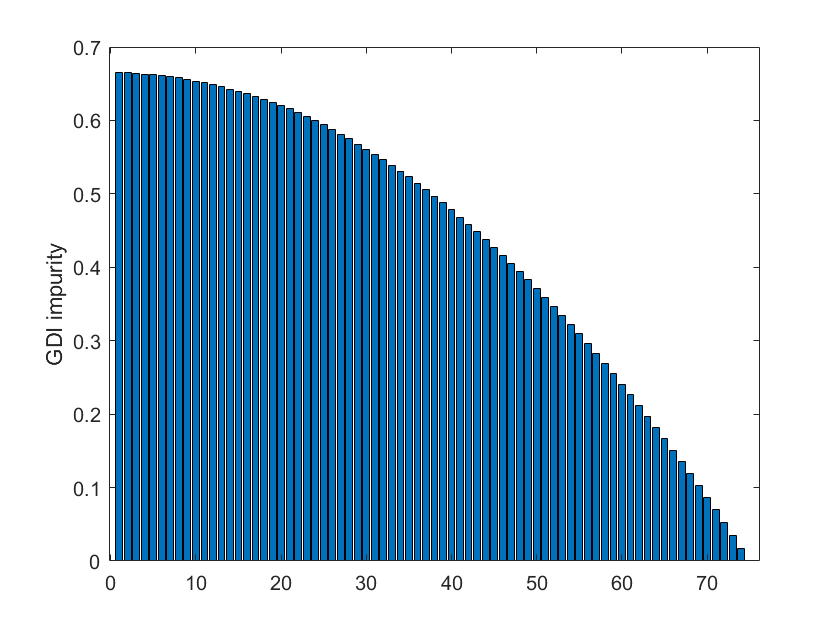

train_labels_copy = train_labels;
for i = 1:length(train_labels_copy)
    if train_labels_copy(i) ~= 'setosa'
        train_labels_copy(i) = 'setosa';
    else
        continue;
    end
    impurity(end+1) = mytree.weightedImpurity(my_m, train_labels_copy);
end
bar(impurity);
ylabel('GDI impurity');

You can see the GDI score gradually reducing down to zero as the class label impurity decreases, and eventually becomes completely pure (all the labels are setosa).

So when the `trySplit()` function calculates a measure of the current impurity within the node's class labels, you now have a good sense of what is happening. Make sure you can find the call to the `weightedImpurity()` function and the `weightedImpurity()` function itself. Although we haven't yet described every line in the `weightedImpurity()` function (we'll return to do this later on) you should be able to spot the loop over all the class labels, the calculation of the fraction of class labels in the current class ($p_i$) and the subtraction of the final value in the running total from the number 1. Take time to add comments.

## Decision Tree training: what splits to consider?

The next thing that the `trySplit()` function does is to look at each of the possible ways to split the training data in the current node. It considers splitting on every feature (so in our particular example it considers splitting on sepal length, splitting on sepal width, splitting on petal length, and splitting on petal width). What exact values of each of those features should it consider splitting on? For example, petal lengths that are less than or equal to 1 or greater than 1, petal lengths that are less than or equal to 2 or greater than 2, ...? What specific values of each feature would it be sensible to consider? By default, the Matlab `fitctree()` function will consider splitting on every unique value of the feature that is present in the training data, and the mytree class does the same. This will give every possible division of the class labels, with no possible splits missed and none repeated.

You should be able to find a nested loop (a loop within a loop) in the `trySplit()` function that is considering splitting on every unique value (inner loop) of every feature (outer loop) in the table of training data stored in the current node. The basic structure of the code is shown below, with some extra debug added to aid understanding, and running on an example node containing just the first 5 rows of our training data table:

% make our own example node for testing:
node.examples = train_examples(1:1:5,:);
node.labels = train_labels(1:1:5);

for i=1:size(node.examples,2)
    fprintf('evaluating possible splits on feature %d/%d\n', i, size(node.examples,2));
    % reorder the examples, and the labels, based on this feature:
    [ps,n] = sortrows(node.examples,i);
    ls = node.labels(n);
    
    % code omitted...
    
    for j=1:(size(ps,1)-1)
        if ps{j,i} == ps{j+1,i}
            continue;
        end
        fprintf('trying a split around the unique value: %f\n', ps{j,i});
        
        % code omitted...
        
    end
end

evaluating possible splits on feature 1/4


trying a split around the unique value: 4.600000
trying a split around the unique value: 4.800000
trying a split around the unique value: 5.100000
trying a split around the unique value: 6.300000


evaluating possible splits on feature 2/4


trying a split around the unique value: 2.500000
trying a split around the unique value: 3.000000
trying a split around the unique value: 3.100000
trying a split around the unique value: 3.400000


evaluating possible splits on feature 3/4


trying a split around the unique value: 1.400000
trying a split around the unique value: 1.500000
trying a split around the unique value: 4.900000


evaluating possible splits on feature 4/4


trying a split around the unique value: 0.100000
trying a split around the unique value: 0.300000
trying a split around the unique value: 1.500000


Next we'll have a careful look at what's happening in this code snippet, but to help us analyse it, let's look at the table of training data we're trying to split:

node.examples

ans = 5×4 table
    sepal_length    sepal_width    petal_length    petal_width
    ____________    ___________    ____________    ___________

        4.6             3.4            1.4             0.3    
        5.1             3.8            1.5             0.3    
        4.8               3            1.4             0.1    
        6.9             3.1            4.9             1.5    
        6.3             2.5              5             1.9    


And the corresponding 5 class labels:

node.labels

ans = 5×1 categorical array
     setosa 
     setosa 
     setosa 
     versicolor 
     virginica 


So we have 5 examples in our testing node, and each one consists of 4 different feature values (sepal length, sepal width, petal length, petal width), and an associated class label (either setosa, versicolor or virginica). The first (outer) loop, above, moves us through each of the features in the data by moving us across the columns of our table. The number of columns, or the width of the table stored in `node.examples` is given by:

size(node.examples, 2)

ans = 4

For a given feature/column in our table, we want to consider splitting our 5 training examples up into two separate tables, based on each of the unique values we have observed for that feature. For a particular unique value, the first table would contain all the examples where that feature was *less than or equal to* that value, and the second table would contain all the examples where that feature was *greater than* that value. The easiest way to produce these different splits is to reorder the rows of the table based on the feature/column that we're currently interested in. We can use Matlab's `sortrows()` function to do this. You should be able to find it being called in the code snippet above, and in the original `trySplit()` function. Here's an example of reordering the rows in our table based on the values in the first column:

[ps,n] = sortrows(node.examples,1)

ps = 5×4 table
    sepal_length    sepal_width    petal_length    petal_width
    ____________    ___________    ____________    ___________

        4.6             3.4            1.4             0.3    
        4.8               3            1.4             0.1    
        5.1             3.8            1.5             0.3    
        6.3             2.5              5             1.9    
        6.9             3.1            4.9             1.5    


n =      1
     3
     2
     5
     4


See that `ps` contains the sorted table and `n` contains the indices of the newly ordered rows in the *original* table. This is useful because we can use it to read out a correctly ordered version of the class labels (we've done similar things with the `min()` and `sort()` function in previous labs):

ls = node.labels(n)

ls = 5×1 categorical array
     setosa 
     setosa 
     setosa 
     virginica 
     versicolor 


Working with our newly re-ordered table rows, it's really easy to create the different splits of the training examples that we're interested in. For 5 unique values of a feature, there are 4 possible splits, and in terms of the rows of `ps` they contain, the splits look like this:

- 1 and 2,3,4,5

- 1,2 and 3,4,5

- 1,2,3 and 4,5

- 1,2,3,4 and 5

Generally, if all the values of the feature in the column we're interested in are unique, then the number of possible splits is always one less than the number of examples. The second (inner) loop, in the code snippet above (and in the original `trySplit()` function), moves us through each of the possible splits. Notice that it loops from 1 up to the height of `ps` minus 1:

(size(ps,1)-1)

ans = 4

Notice that the 3rd and 4th columns of our table (the petal length and petal width features) don't contain all unique examples:

node.examples

ans = 5×4 table
    sepal_length    sepal_width    petal_length    petal_width
    ____________    ___________    ____________    ___________

        4.6             3.4            1.4             0.3    
        5.1             3.8            1.5             0.3    
        4.8               3            1.4             0.1    
        6.9             3.1            4.9             1.5    
        6.3             2.5              5             1.9    


This means we don't need to consider as many splits and you may have noticed in the debug produced by the code snippet that there are only 3 splits considered for both the petal length and the petal width features (scroll back up and have a look if not).

You should be able to identify code in the second (inner) for loop that checks to see if the next value in the current feature column of the re-ordered table is identical to the current one, and skips us on to the next iteration if it is. This code prevents us from trying to split on the same value more than once.

Make sure you can find each of the lines of code described in this section in the original `trySplit()` function. Take time to add comments.

## Decision Tree training: to split, or not to split (part 1)

So the code we analysed in the previous section allows the `trySplit()` function to generate all the possible splits from every unique value of every feature, but how does it decide which of those splits is the best? And indeed whether the data should be split at all?

The question the algorithm asks is: will this split reduce the overall level of impurity amongst the class labels? If no splits will, then a node won't be split. If one split does then the node will be split based on the corresponding feature value. If more than one split does, then the node will be split based on the feature value that brought about the *greatest* reduction in impurity.

And how do we measure impurity? Just as before, we use the GDI score implemented by the `weightedImpurity()` function.

## Decision Tree training: the GDI weighting factor

The only part of the `weightedImpurity()` function we haven't yet described is the `weight` variable, which is used to re-scale each GDI score. This variable models the probability of arriving in a particular node when descending the tree from the root node, and it's needed in order to make fair comparisons between the impurity of a single parent node $n_1$ versus two potential child nodes $n_2$ and $n_3$, each with their own respective sizes and impurities.

For example, imagine a split where the first child node $n_2$ is completely pure, but leaves a second node $n_3$ with an increased impurity versus the original parent $n_1$. Should we make the split, or not? To make this decision we need to think about the *probability* that we will descend into either of the child nodes in a future prediction phase. If we are highly likely to descend into the more impure node $n_3$ and highly unlikely to descend into the perfectly pure node $n_2$, then making the split could be a bad idea.

To make the decision we can weight the respective GDI scores for each node, $g_1$, $g_2$ and $g_3$ by the probabilities that we'll descend into those nodes in a future prediction phase: $p_1$, $p_2$ and $p_3$. If and only if the weighted impurity score for the parent is higher than the combined weighted impurity scores for the children should we make the split. Or as a mathematical condition, we would require that: $\left(p_1 \times g_1 \right)>\left(p_2 \times g_2 +p_3 \times g_3 \right)$.

So how to get the probabilities? Providing our training data is representative, then the probability of descending into any node is given by the number of examples in that node divided by the total number of examples in the tree. This is the fraction of examples generated by the real-world system behind our data that meet each of the necessary criteria at the higher levels of our decision tree in order to end up descending into our current node.

Note that $p_2 +p_3$ will always equal $p_1$ because the number of examples in both $n_2$ and $n_3$ must total the number of examples in $n_1$ (the child nodes are created from dividing up the data in the parent node). What we are essentially considering is how likely we are to get into one child node versus the other (and how that compares with just staying in the parent node).

Make sure you can find the calculation and application of the `weight` variable in the `weightedImpurity()` function. Take time to add comments. Don't worry about capturing every single aspect of the explanation above. It is sufficient to note that the weighting factor allows for fair comparisons between different numbers of nodes each with different sizes.

## Decision Tree training: to split, or not to split (part 2)

So returning to the nested for loop in the `trySplit()` function, you should be able to identify a line of code that calculates the GDI for the two collections of class labels created by a given split, adds them together, and subtracts them from the GDI score for the original table. If the result is positive then the split produces a reduction in impurity. Make sure you can identify the relevant line. Take time to add comments.

The problem we have, as we loop over the different features in the training examples and look at all the different possibilities for splitting, is that many of them may produce reductions in impurity and we need to keep track of which one produces the *greatest* reduction.

As the nested for loop proceeds, the code keeps track of the largest reduction in impurity for each individual feature (in an array called `biggest_reduction`) and the index of the feature value on which the split took place (in an array called `biggest_reduction_index`). Once the loops have completed, the code compares the largest impurity reductions achieved across each of the different features and finds the biggest (by calling `max()` on the `biggest_reduction` array) and the index of the specific feature value associated with that reduction (by looking inside the same element of `biggest_reduction_index`).

Finally, the `trySplit()` function checks that the overall winning reduction was greater than zero (i.e., that it was possible to achieve a *reduction* in impurity through splitting) and if it was, then it proceeds to split the node into two further nodes (more on this in the next section...). If the winning reduction was *not* greater than zero, then the `trySplit()` function simply returns and the current node is left alone (it isn't split).

Make sure you can find each of the relevant lines of code before continuing. Take time to add comments.

## Decision Tree training: making children

If the analysis of possible splits leads to a winner that reduces the overall impurity (see previous section) then our job is to make two new child nodes, descending directly from the original node, with one containing the first portion of training data, and the other containing the second portion. There's nothing too tricky here, but make sure that you can follow what happens in the `trySplit()` code. We go through the important steps below. Take time to add comments as you read through.

The first thing to be aware of is that our table of training data `ps` is still sorted based on the values in the final feature column (the last column our nested for loop analysed). It's *not* ordered based on the winning feature and we need to do that before we go any further. Make sure you can find the second call to the `sortrows()` function.

For the *current* node (the one we have been investigating whether or not to split) we can then set up a number of structure fields that have been empty up until this point:

- `splitFeature` - the index of the table column containing the feature we have decided to split the training data on

- `splitFeatureName` - the name of the table column containing the feature we have decided to split the training data on (useful to print out in text-based visualisation of the final tree)

- `splitValue` - the value of the feature that should be used for splitting testing data in future

You might expect that the `splitValue` would simply be equal to the unique training value that we split on. We can do slightly better than that, though. We also know that moving up to the next highest value of that feature in the training data *didn't* produce a better split (i.e., it didn't reduce the overall impurity quite as much). So we should try to say something about the space *in between* those two feature values. We take the simple step of choosing our `splitValue` as the value exactly half way in between those two values. Make sure you can find the line of code where this happens and you're happy with how it works.

We can also clear some fields in the current node structure that have contained values up until this point:

- `examples` - we can delete the training examples from the current node as they will move down to live in the node's children

- `labels` - as above

- `prediction` - we can delete the prediction associated with this node as it will never be used to generate a prediction during the prediction phase (only leaf nodes are used for prediction, and we're in the process of converting this node into a branch node with children of its own)

It wouldn't matter if we left any of these things, but it saves us from unnecessarily duplicating data across the structure and making it bigger than it needs to be.

Now we need to make the two new children that will descend from this node. The basic step is to create two new empty nodes by copying the `m.emptyNode` structure we defined in the `fit()` function. These nodes live inside the `children` field of the current node structure, which is a cell array. Make sure you can find the lines where `node.children{1}` and `node.children{2}` are written. There are also a number of other fields we can write for each child node:

- `number` - a unique number for the node within the overall tree (helps us to keep track of how many nodes we have in total and to produce text-based descriptions of trained trees)

- `examples` - for the first child this will be all the rows from the parent's table of training data which have a value in the `splitFeature` column less than or equal to the `splitValue`. For the second child, it will be all the remaining rows.

- `labels` - the class labels associated with the examples in each child node

- `prediction` - the class label we would predict from this node during a future prediction phase, based on the mode (most common) class label in `labels`

Before proceeding to the next section, make sure you can find the lines of code where these things happen and you're happy with how they work. Take time to add comments.

## Decision Tree training: children making children?

The very last thing that the `trySplit()` function will do, is to see if either of the new child nodes themselves could be split again to further reduce the overall impurity across their class labels. Make sure you can find the lines where `trySplit()` calls itself again, on both the first and second child of the current node. Take time to add comments.

These calls will continue, recursively, until our original root node has been divided up into a complete tree of nodes which may spread across many levels containing many different nodes and branches. Thus, our one original call to `trySplit()` from the `fit()` function, passing in a single node, results in the generation of the entire tree.

## Decision Tree prediction: overview

The `predict()` function in the mytree class is responsible for performing all the steps involved in prediction. Let's call it again:

% use our model to classify the testing dataset:
my_predictions = mytree.predict(my_m, test_examples);

classifying example 1/38
classifying example 2/38
classifying example 3/38
classifying example 4/38
classifying example 5/38
classifying example 6/38
classifying example 7/38
classifying example 8/38
classifying example 9/38
classifying example 10/38
classifying example 11/38
classifying example 12/38
classifying example 13/38
classifying example 14/38
classifying example 15/38
classifying example 16/38
classifying example 17/38
classifying example 18/38
classifying example 19/38
classifying example 20/38
classifying example 21/38
classifying example 22/38
classifying example 23/38
classifying example 24/38
classifying example 25/38
classifying example 26/38
classifying example 27/38
classifying example 28/38
classifying example 29/38
classifying example 30/38
classifying example 31/38
classifying example 32/38
classifying example 33/38
classifying example 34/38
classifying example 35/38
classifying example 36/38
classifying example 37/38
classifying example 38/38


Have a look at the mytree class and make sure you can find the `predict()` function.

Here are the important steps that take place during prediction with the Decision Tree algorithm. After each one, in brackets, is a rough indication of how complicated that step is to understand, e.g. "easy", "moderately hard", etc:

Prediction

- For each new test example we are trying to classify, descend the tree, applying the splitting rules at each node (moderate)

- Once a leaf node is reached, classify the test example using the predicted value for that node (easy)

In the following sections we work through each of steps in greater detail, looking at the corresponding lines of code in the mytree class. You should make sure you have the mytree class open ready to read and add your comments to, and you should make sure you look after your copy of the file carefully in between now and the in-class test.

## Naive Bayes prediction: one example at a time

The first thing to notice is that the `predict()` function itself doesn't really do all that much...

The `predict()` function has been written to mimic the built-in Matlab function with the same name and it will accept as many different test examples as you want to want to pass it all bundled together in a single big table (the second argument of the function call).

All it then does is to loop through all of the test examples in the table and call the `predict_one()` function on each one. Remember there's one example per row in our tables, so to loop over the number of examples, we'd need to find the height of the table. We can get this with a call to `size(test_examples, 1)` and you should be able to identify the point where this call happens. You should also be able to identify the line of code that extracts a single example from the table, the line that passes it to `predict_one()`, and what happens to the result returned by `predict_one()`. Take time to add comments.

The next section moves on to look at the `predict_one()` function in more detail.

## Naive Bayes prediction: descending the tree

The `predict_one()` function has one simple job: to descend the trained decision tree, applying the splitting rules defined in each node by consulting its `splitFeature` and `splitValue` fields and comparing against the value of the corresponding feature in the current test example, until, eventually, it reaches a leaf node. Once there, it returns the node's class prediction.

The `predict_one()` function calls the `descend_tree()` function to perform the job of descending the tree and returning the child node that is eventually reached. Make sure you can find the line where `predict_one()` calls the `descend_tree()` function and the `descend_tree()` function itself. Take time to add comments.

Notice that the `descend_tree()` function is also recursive, either applying the rule in the current node if it is a branch node, and then calling itself again passing in the appropriate child, or returning the node itself if it is a leaf node.

Let's use the `descend_tree()` function to descend our tree based on the feature values in the first testing example:

node = mytree.descend_tree(my_m.tree, test_examples{1,:})

node = struct with fields:
              number: 2
            examples: [38×4 table]
              labels: [38×1 categorical]
          prediction: setosa
     impurityMeasure: 0
            children: {}
        splitFeature: []
    splitFeatureName: []
          splitValue: []


## Naive Bayes prediction: generating a label

Once the "winning" leaf node has been returned to `predict_one()` it extracts the contents of its `prediction` field and returns it. Remember the `prediction` field comes from the mode (most common) class label in the data the node stores. Take time to add a comment.

Note that because we calculate the prediction values for each node during training, the number of training examples in a tree will have no impact on the time it takes to classify new examples in the prediction phase. This will only depend on the structure of the tree and the number of nodes it contains, and, therefore, how long it takes to descend it to a leaf node.

Let's extract the contents of the prediction field for the node we returned in the previous section:

node.prediction

ans = categorical
     setosa 


## Tasks

Review your copy of the mytree class and check you are happy with the overall standard of the commenting:

- If you forget a detail about Decision Tree classification under the pressure of the in-class test conditions, are your comments good enough to help you figure it out?

- Have you commented each line of code? (Or some comments adequately cover multiple lines of code)

- Have you included overview comments above each of the functions?

- Have you focused on the *why* rather than the *what*? (see also the "Writing good comments" document on Moodle)